# AMECH HW13

*Steven Henderson*

m = 1 ;
M = [
    m 0 ;
    0 m
    ] ; % mass matrix with two mass system
C = [
    2 -1 ;
    -1 2
    ] ; % Coeffiecient matrix C
[V, D] = eig(M^(-1)*C) % Find eigen values and vectors

V =    -0.7071   -0.7071
   -0.7071    0.7071


D =      1     0
     0     3


L_0 = 0.2 ; % Original length of strings in meters
T = 3 ; % The constant tension in the strings
omega  = sqrt(diag(D)*T / L_0)  % Angular frequency in rad/s

omega =     3.8730
    6.7082


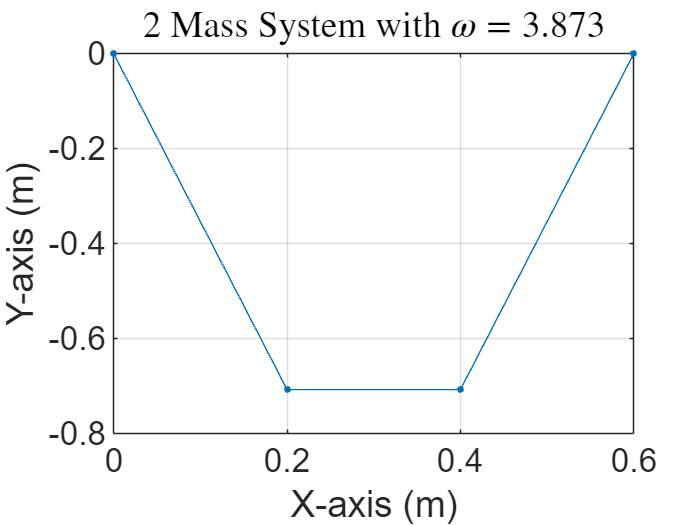

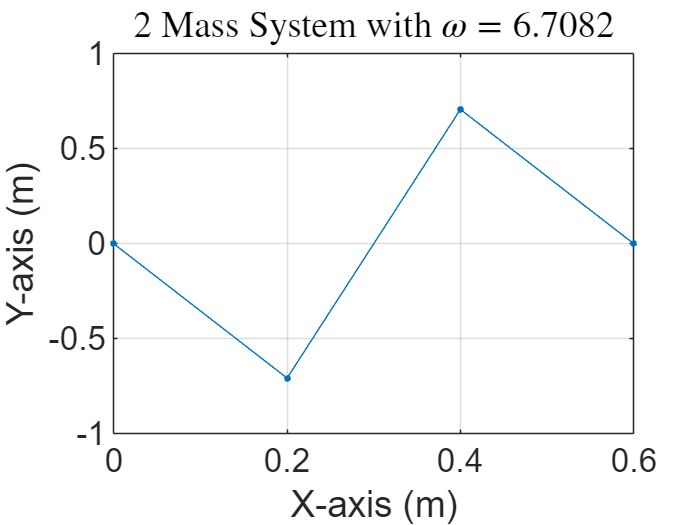


for i = 1:length(V(1, :))
    figure
    plot(0:L_0:3*L_0, [0; V(:, i); 0], '.-', 'MarkerSize', 12)
    ylabel("Y-axis (m)")
    xlabel("X-axis (m)")
    set(gca, "fontsize", 20)
    title(['2 Mass System with $\omega=$', num2str(omega(i))], 'Interpreter', 'latex')
    grid on
end

% For 8 masses
m = 1 ;
M = diag([m, m, m, m, m, m, m, m]) ; % mass matrix with two mass system
C = diag([2, 2, 2, 2, 2, 2, 2, 2]) + diag([-1, -1, -1, -1, -1, -1, -1], -1) + diag([-1, -1, -1, -1, -1, -1, -1], 1) ; % Coeffiecient matrix C
[V, D] = eig(M^(-1)*C) % Find eigen values and vectors

V =     0.1612   -0.3030   -0.4082    0.4642   -0.4642    0.4082   -0.3030   -0.1612
    0.3030   -0.4642   -0.4082    0.1612    0.1612   -0.4082    0.4642    0.3030
    0.4082   -0.4082   -0.0000   -0.4082    0.4082   -0.0000   -0.4082   -0.4082
    0.4642   -0.1612    0.4082   -0.3030   -0.3030    0.4082    0.1612    0.4642
    0.4642    0.1612    0.4082    0.3030   -0.3030   -0.4082    0.1612   -0.4642
    0.4082    0.4082   -0.0000    0.4082    0.4082   -0.0000   -0.4082    0.4082
    0.3030    0.4642   -0.4082   -0.1612    0.1612    0.4082    0.4642   -0.3030
    0.1612    0.3030   -0.4082   -0.4642   -0.4642   -0.4082   -0.3030    0.1612


D =     0.1206         0         0         0         0         0         0         0
         0    0.4679         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    1.6527         0         0         0         0
         0         0         0         0    2.3473         0         0         0
         0         0         0         0         0    3.0000         0         0
         0         0         0         0         0         0    3.5321         0
         0         0         0         0         0         0         0    3.8794


L_0 = 0.2 ; % Original length of strings in meters
T = 3 ; % The constant tension in the strings
omega  = sqrt(diag(D)*T / L_0)  % Angular frequency in rad/s

omega =     1.3451
    2.6493
    3.8730
    4.9790
    5.9338
    6.7082
    7.2788
    7.6283


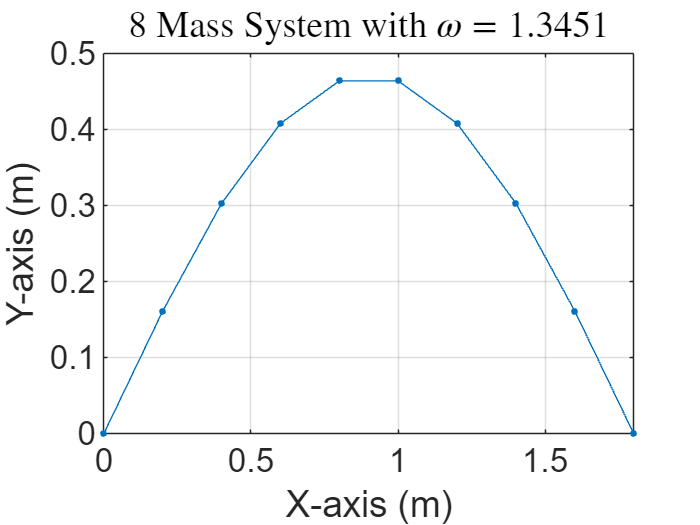

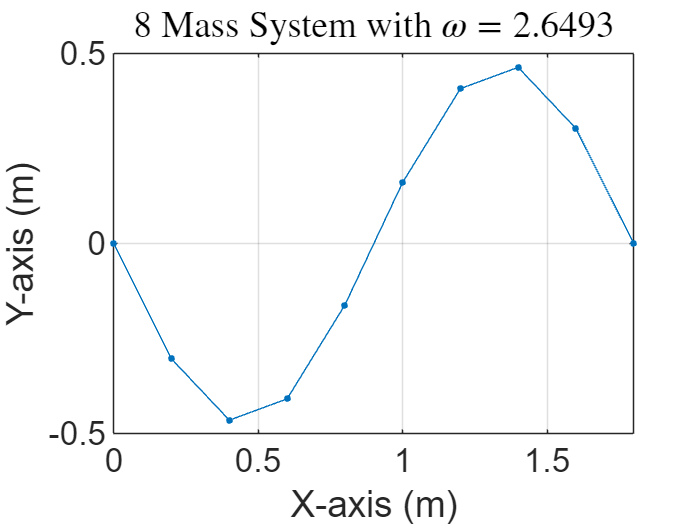

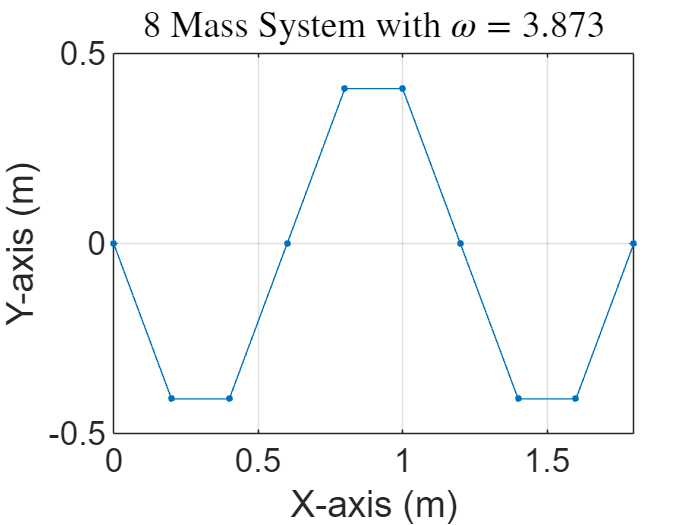

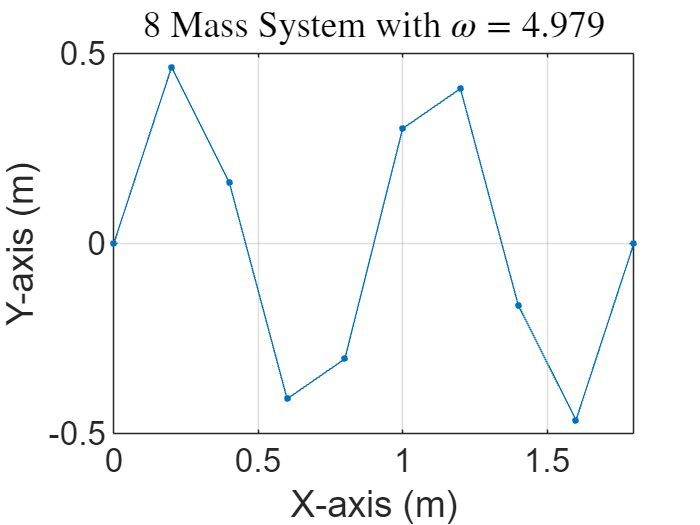

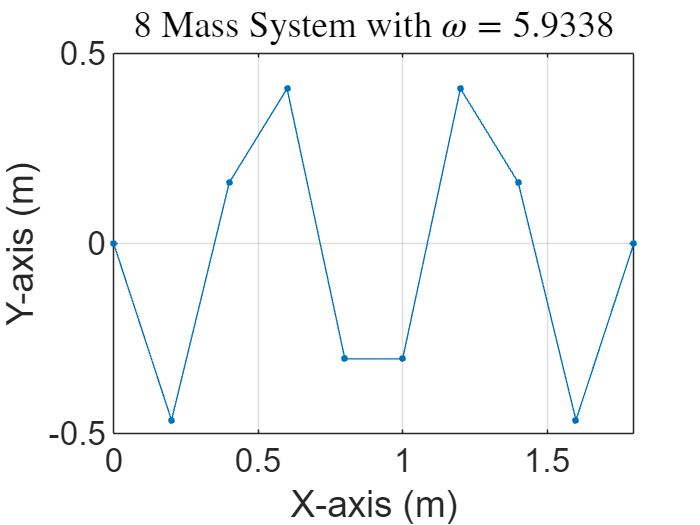

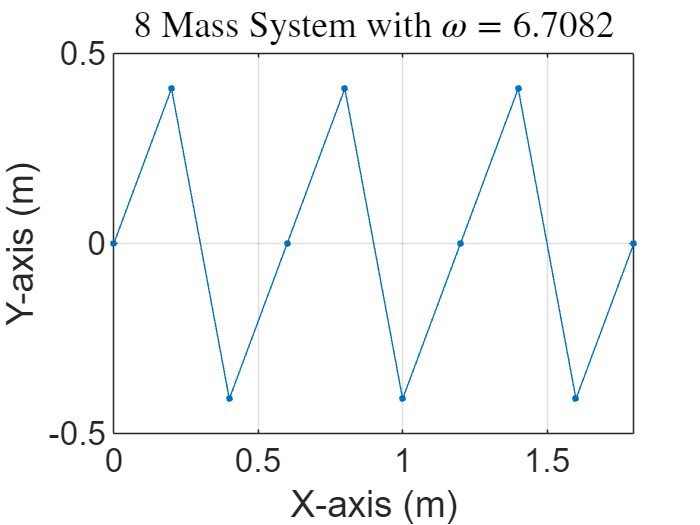

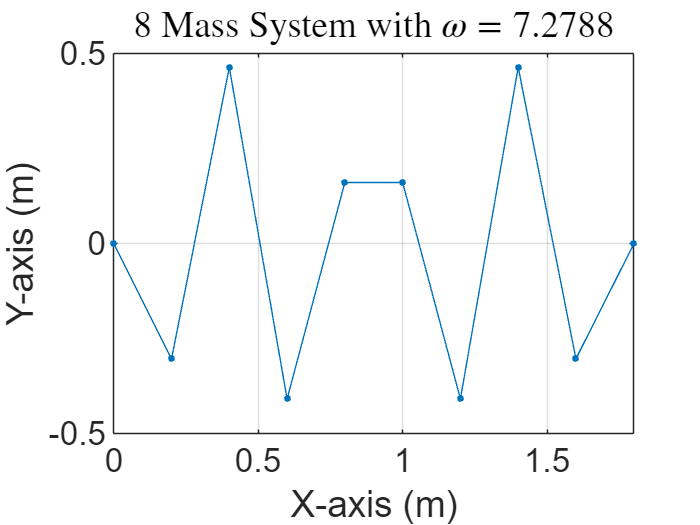

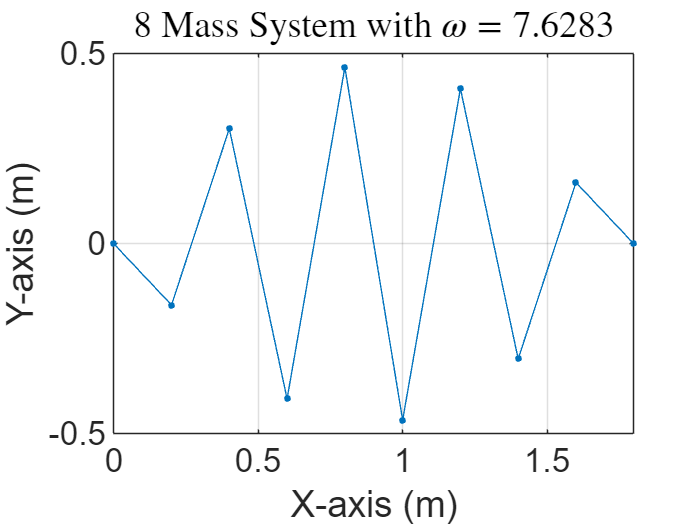

for i = 1:length(V(1, :))
    figure
    plot(0:L_0:9*L_0, [0; V(:, i); 0], '.-', 'MarkerSize', 12)
    ylabel("Y-axis (m)")
    xlabel("X-axis (m)")
    set(gca, "fontsize", 20)
    xlim([0, 9*L_0])
    title(['8 Mass System with $\omega=$', num2str(omega(i))], 'Interpreter', 'latex')
    grid on
end